## COVID-19 in BC

**Objective: **To fit the two-age group *SI(R)I(UR)R *model of COVID-19 transmission to the reported case data under various constraints.

## Initialization 

clear all; clc;

%% Select region, timeframe, age-cutoff
region = 'BC';
start_date = 'Jan 01, 2021';
end_date = 'Jan 30, 2021';
age_cutoff = 50;
Month = 'Dec';

%% Set parameters
D_T = 5.0;
D = [D_T, D_T]; % Mean infectious period for an I in Group i
T_T = 1;
T = [T_T,T_T]; % Ascertainment fraction of I in Group i 
N = pop_two_groups(age_cutoff); % Estimate for population of Group i 
tspan = 1:1:(datenum(end_date)-datenum(start_date)+1); % timespan over which ODE solved

%% Import data and format to yield cumulative reported cases and initial active cases
dataI = readtable('pathway.csv'); % replace with pathway of file storing cumulative reported case data
observedI = data_selection_two_groups(dataI, start_date, end_date);
y1 = init_cond_two_groups(dataI, start_date, D_T, N, T);

## Optimization: fmincon

%% Set transmission parameter constraint (must do so in pred_cases_two_groups.m file)
para0 = [0.2];

%% Calculate theoretical epidemic and residual sum of squares
predicted = @(para) pred_cases_two_groups_survey50(T, D, N, para, tspan, y1, Month);
% min_fun = @(para) sum_squares_two_groups(predicted(para), observedI, tspan);
min_fun = @(para) sum_squares_two_groups_norm(predicted(para), observedI, tspan);

%% Optimize parameter given constraint
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0];
ub = [1];


para_opt = fmincon(min_fun, para0,A,b,Aeq,beq,lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


para_opt = 0.0608

error_value = min_fun(para_opt)

error_value = 0.0290



% Specify which survey data to use as constraint
if strcmp(Month,'May')
    beta_opt = para_opt(1)*[1.938461538, 0.711481481; 1.012470588, 1.195088235];
elseif strcmp(Month,'July')
    beta_opt = para_opt(1)*[1.866871795, 0.607846154; 0.848194444, 0.977291667];
elseif strcmp(Month,'Sept')
    beta_opt = para_opt(1)*[3.786944444, 1.286666667; 1.542674419, 1.328313953];
elseif strcmp(Month,'Dec')
    beta_opt = para_opt(1).*[2.202071429, 1.196642857; 1.532119205, 1.181125828];
end

## Plotting

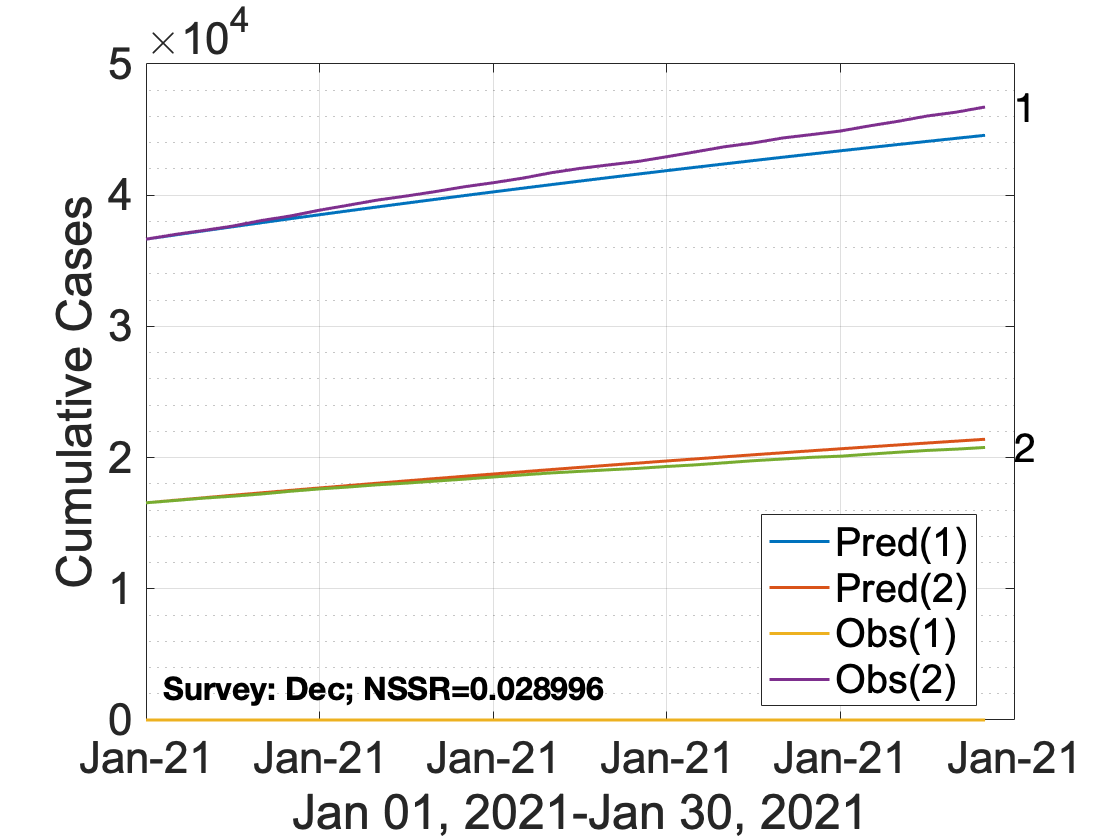

% Plot predicted cases against observed cases 

obsI = observedI;

pred = predicted(para_opt);

for i = tspan
    graphI (i,1) = pred(i,1);
    graphI (i,2) = pred(i,2);
    graphI (i,3) = obsI(i,1);
    graphI (i,4) = obsI(i,2);
end

date_vector = transpose(datetime(start_date):datetime(end_date));

plot(date_vector,graphI,'LineWidth', 1.5, 'MarkerSize', 18)
legend('Pred(1)','Pred(2)','Obs(1)', 'Obs(2)', 'Location', 'Best')
xlabel(strcat(start_date,'-', end_date))
ylabel('Cumulative Cases')
% title(strcat(region, ': 0-', string(age_cutoff), ',', string(age_cutoff), '+'))
xtickformat('MMM-yy')
grid on;
grid minor;
set(gca, 'FontSize', 22)
set(gca, 'FontName', 'Arial')
text(tspan(length(tspan)), graphI (tspan(length(tspan)),3), '1', "FontSize",20)
text(tspan(length(tspan)), graphI (tspan(length(tspan)),4), '2', "FontSize",20)

plot_text = strcat('Survey:', {' '}, Month, '; NSSR=', string(error_value));
text(0.02,0.05, plot_text,'Units','normalized', 'FontSize',16, 'FontWeight','bold')
